# Latency analysis

clc; clear; close all;

## Dataset name

Enter below the dataset name. The file should contain a single json array.

fname_pub = '../data/public_sign-3.json';
fname_priv = '../data/private_sign-3.json';

## Load data

Load the data into memory.

json_pub = load_data(fname_pub);
json_priv = load_data(fname_priv);

## Extract data

Save all the timings for machine.

[ids, mu_pub, std_pub] = analyse(json_pub);
[~, mu_priv, std_priv] = analyse(json_priv);

## Plot

Plot mean and standard deviation.

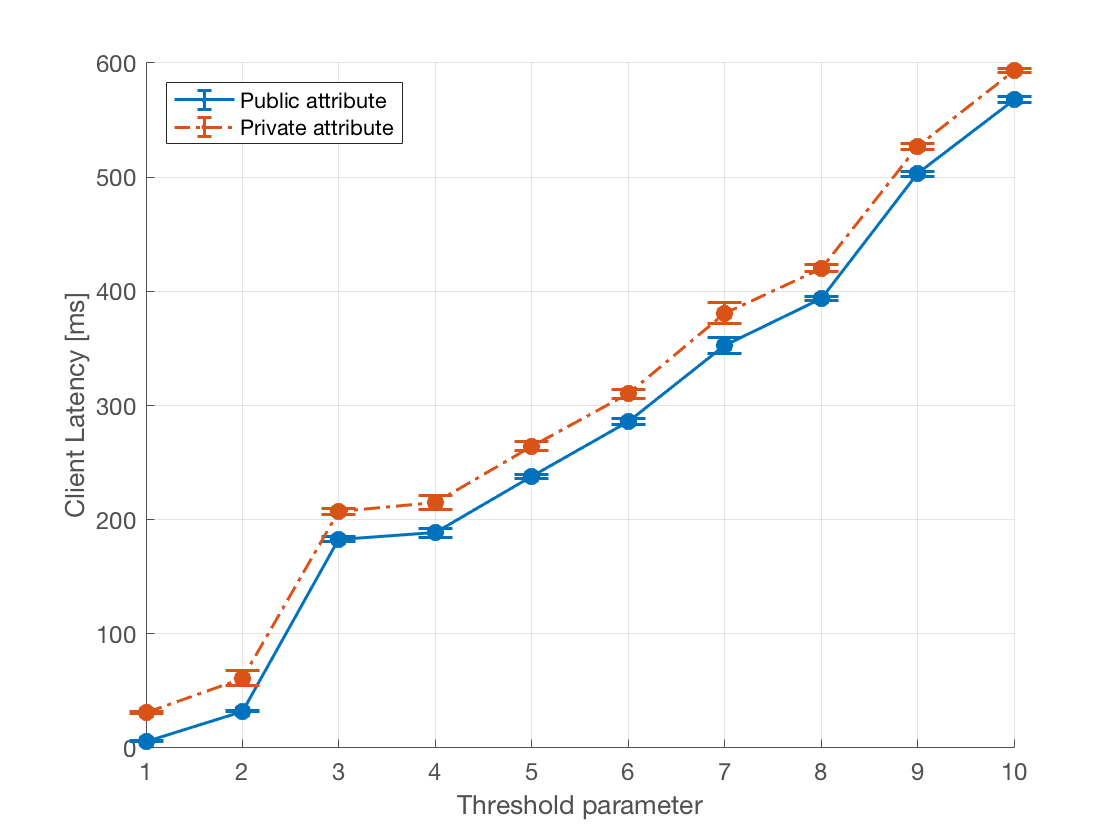

% plot mean and standard deviation
x = 1:length(ids);
createfigure([x' x'],[mu_pub' mu_priv'],[std_pub' std_priv']);

## Plot B&W

Plot mean, standard deviation and cubic spline interpolation in black & white.

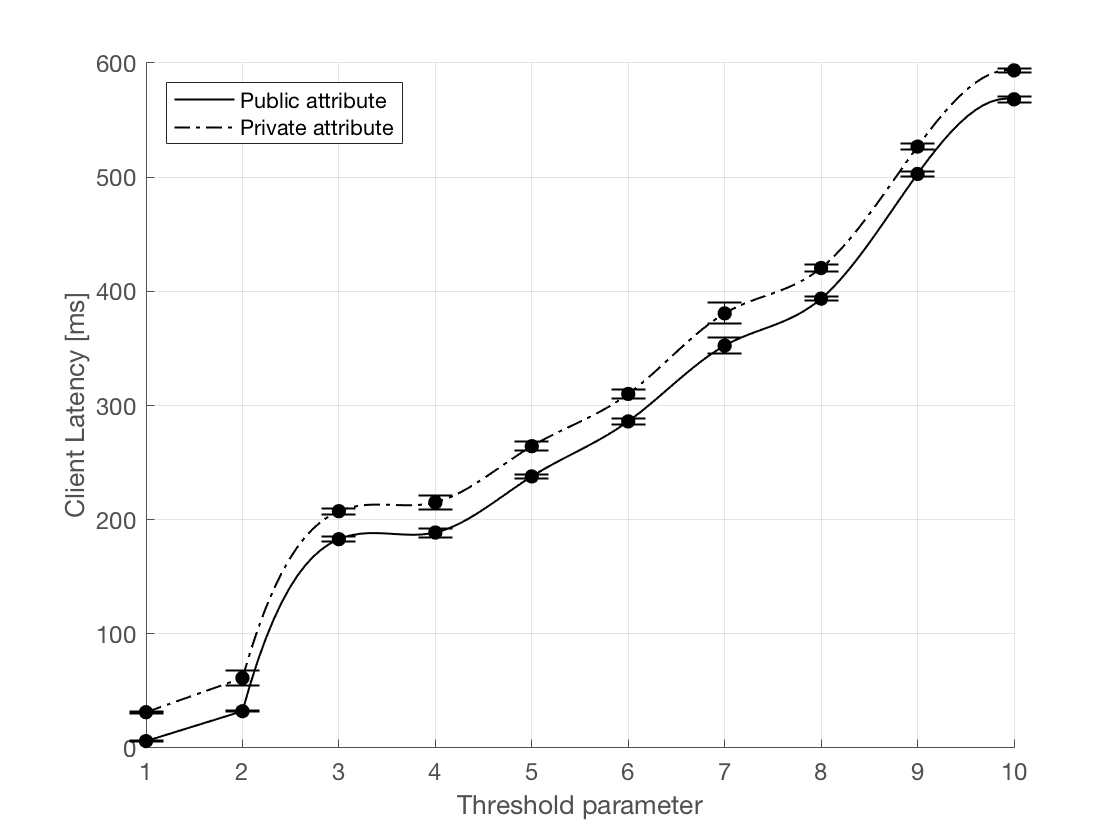

% plot mean and standard deviation
createBWfigure([x' x'],[mu_pub' mu_priv'],[std_pub' std_priv']);

## Stem Plot

Plot mean, standard deviation in discrete values

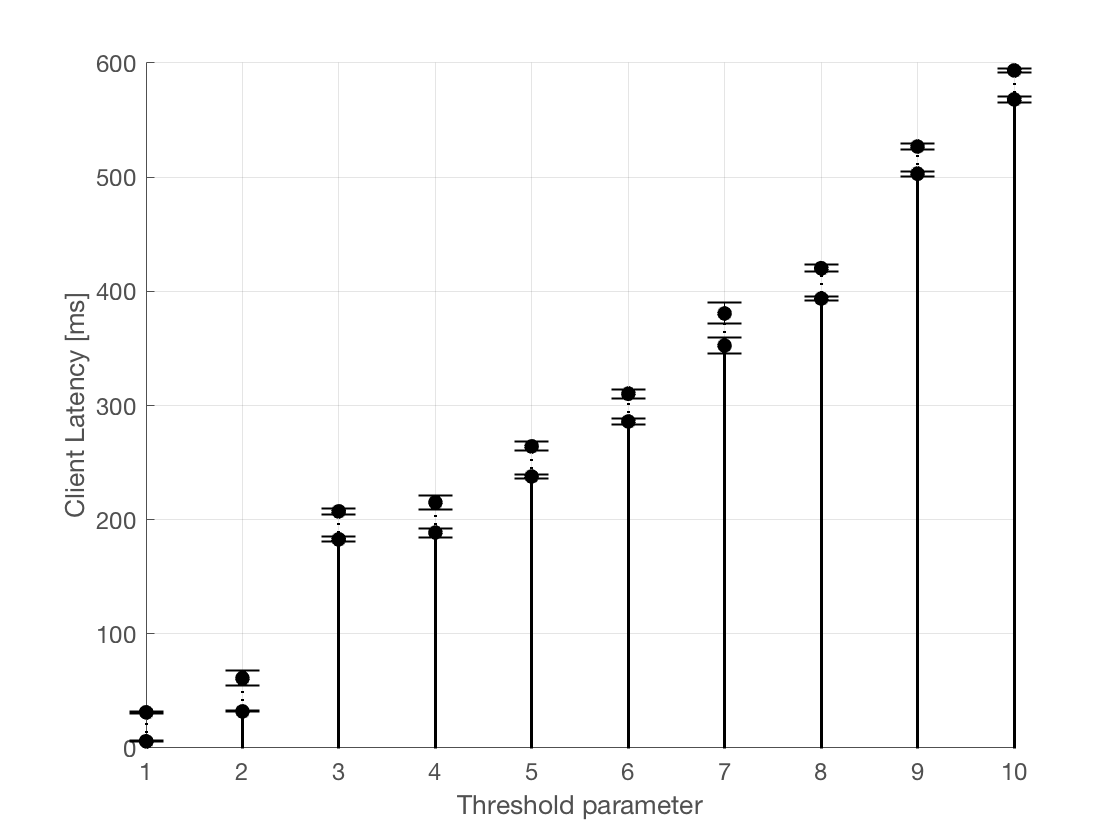

% plot mean and standard deviation
createStemfigure([x' x'],[mu_pub' mu_priv'],[std_pub' std_priv']);